# Solving ODEs with MATLAB: Part 1, Euler Method

Overview

- Why?

- Concept of numerical solutions to differential equations

- Method: Euler

- Method: [MATLAB ODE solvers](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html), e.g., [ode45](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

## Why?

Why do we need to be able to analyze differential equations?

ODEs are the **foundation models **used to describe for much of mechanical, electrical and aerospace engineering:

- Aircraft flight dynamics

- Spacecraft orbital mechanics

- Robot arm movements

- Vibration analysis

- Fluid flow systems - computational fluid dynamics (CFD)

Examples

Six-DOF model for ocean vessels:

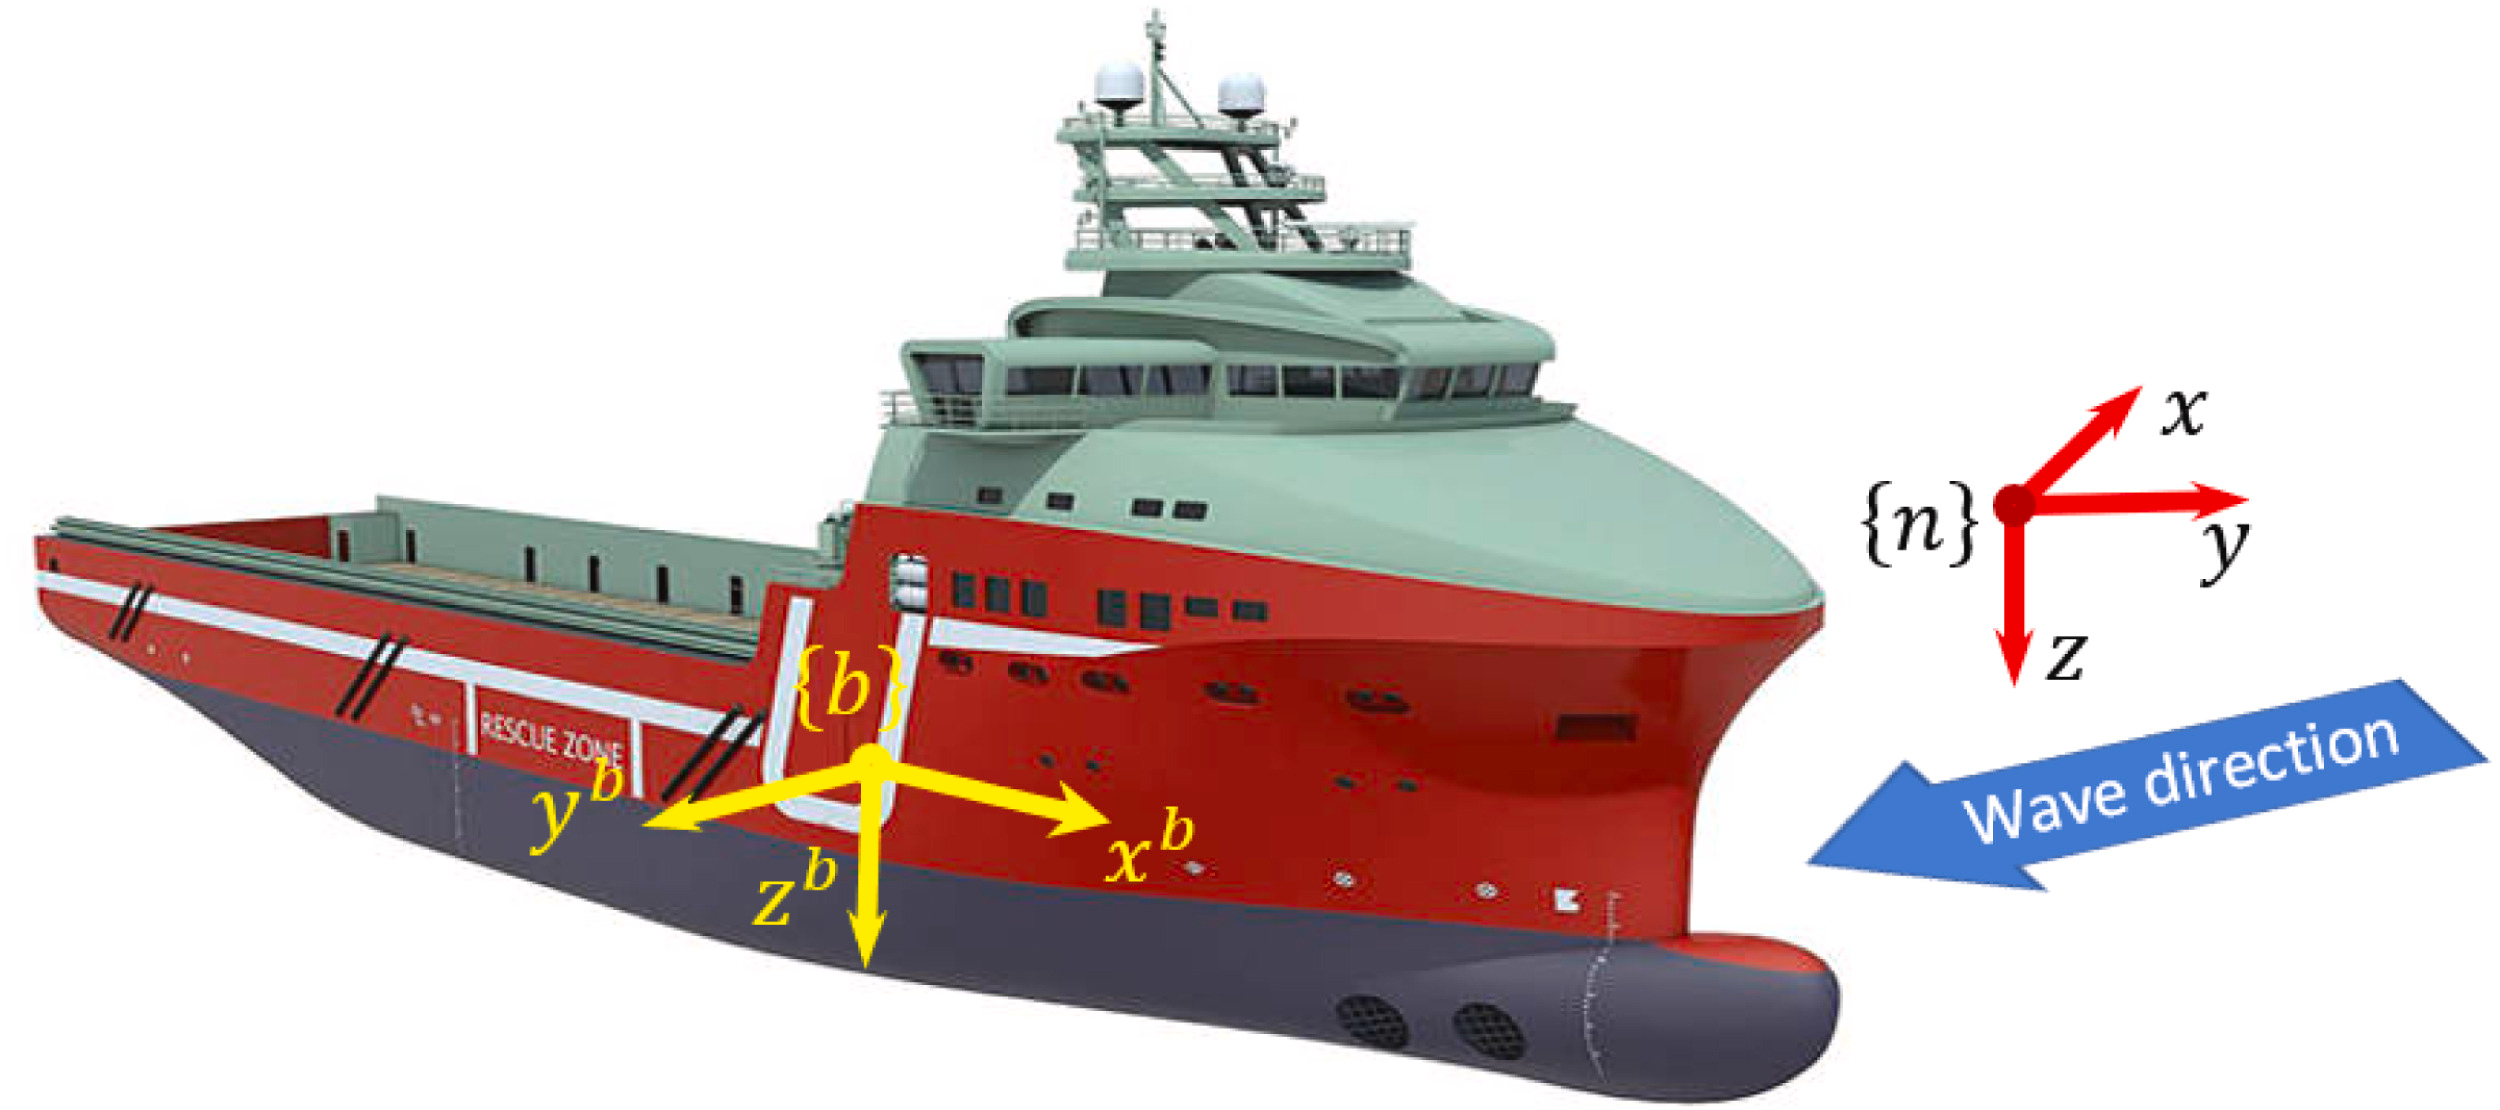

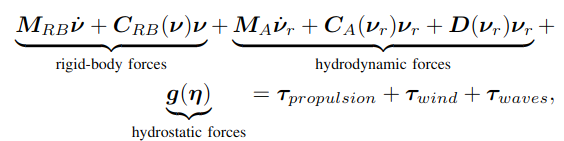

Orbital Mechanics

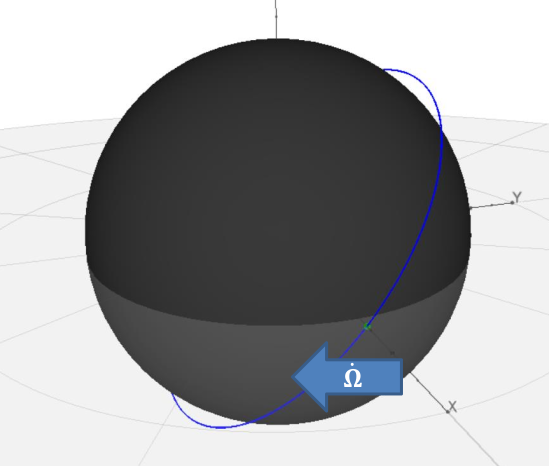

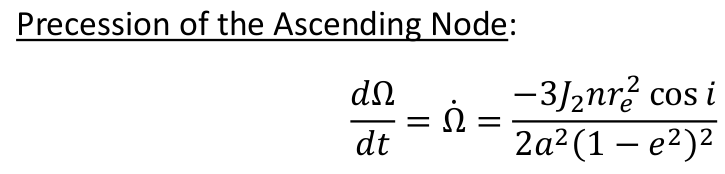

The ability to analyze these models of physical systems enables us to do things like...

- Predict system behavior

- Design control systems

- Optimize performance

- Ensure stability

- Analyze failure modes

Why do we need numerical methods (vice analytical solutions).

- Most real-world ODEs can't be solved analytically

- Complex systems require computational solutions

- Modern engineering relies heavily on simulation

## Comparing analytical (exact) solutions to numerical (approximate) solutions

## Concept of numerical solutions to differential equations

The main goal of numerical ODE solvers is to approximate the true, analytical solution of a differential equation when an exact solution is not available or is too difficult to obtain. This is the case for most real-world engineering problems.

- Discretizing the continuous ODE problem

- Applying an iterative numerical scheme

- Understanding and managing errors

- Handling stiff systems

- Leveraging specialized ODE solver software

## Euler's Method

This simple method for approaching ODEs can help with understanding the general aspects of more complex solvers.  

The reason we start with Euler's method is that it is fairly simple to understand what is going on "under the hood" and it is a surrogate for more complex solvers that can tackle more challenging problems.  

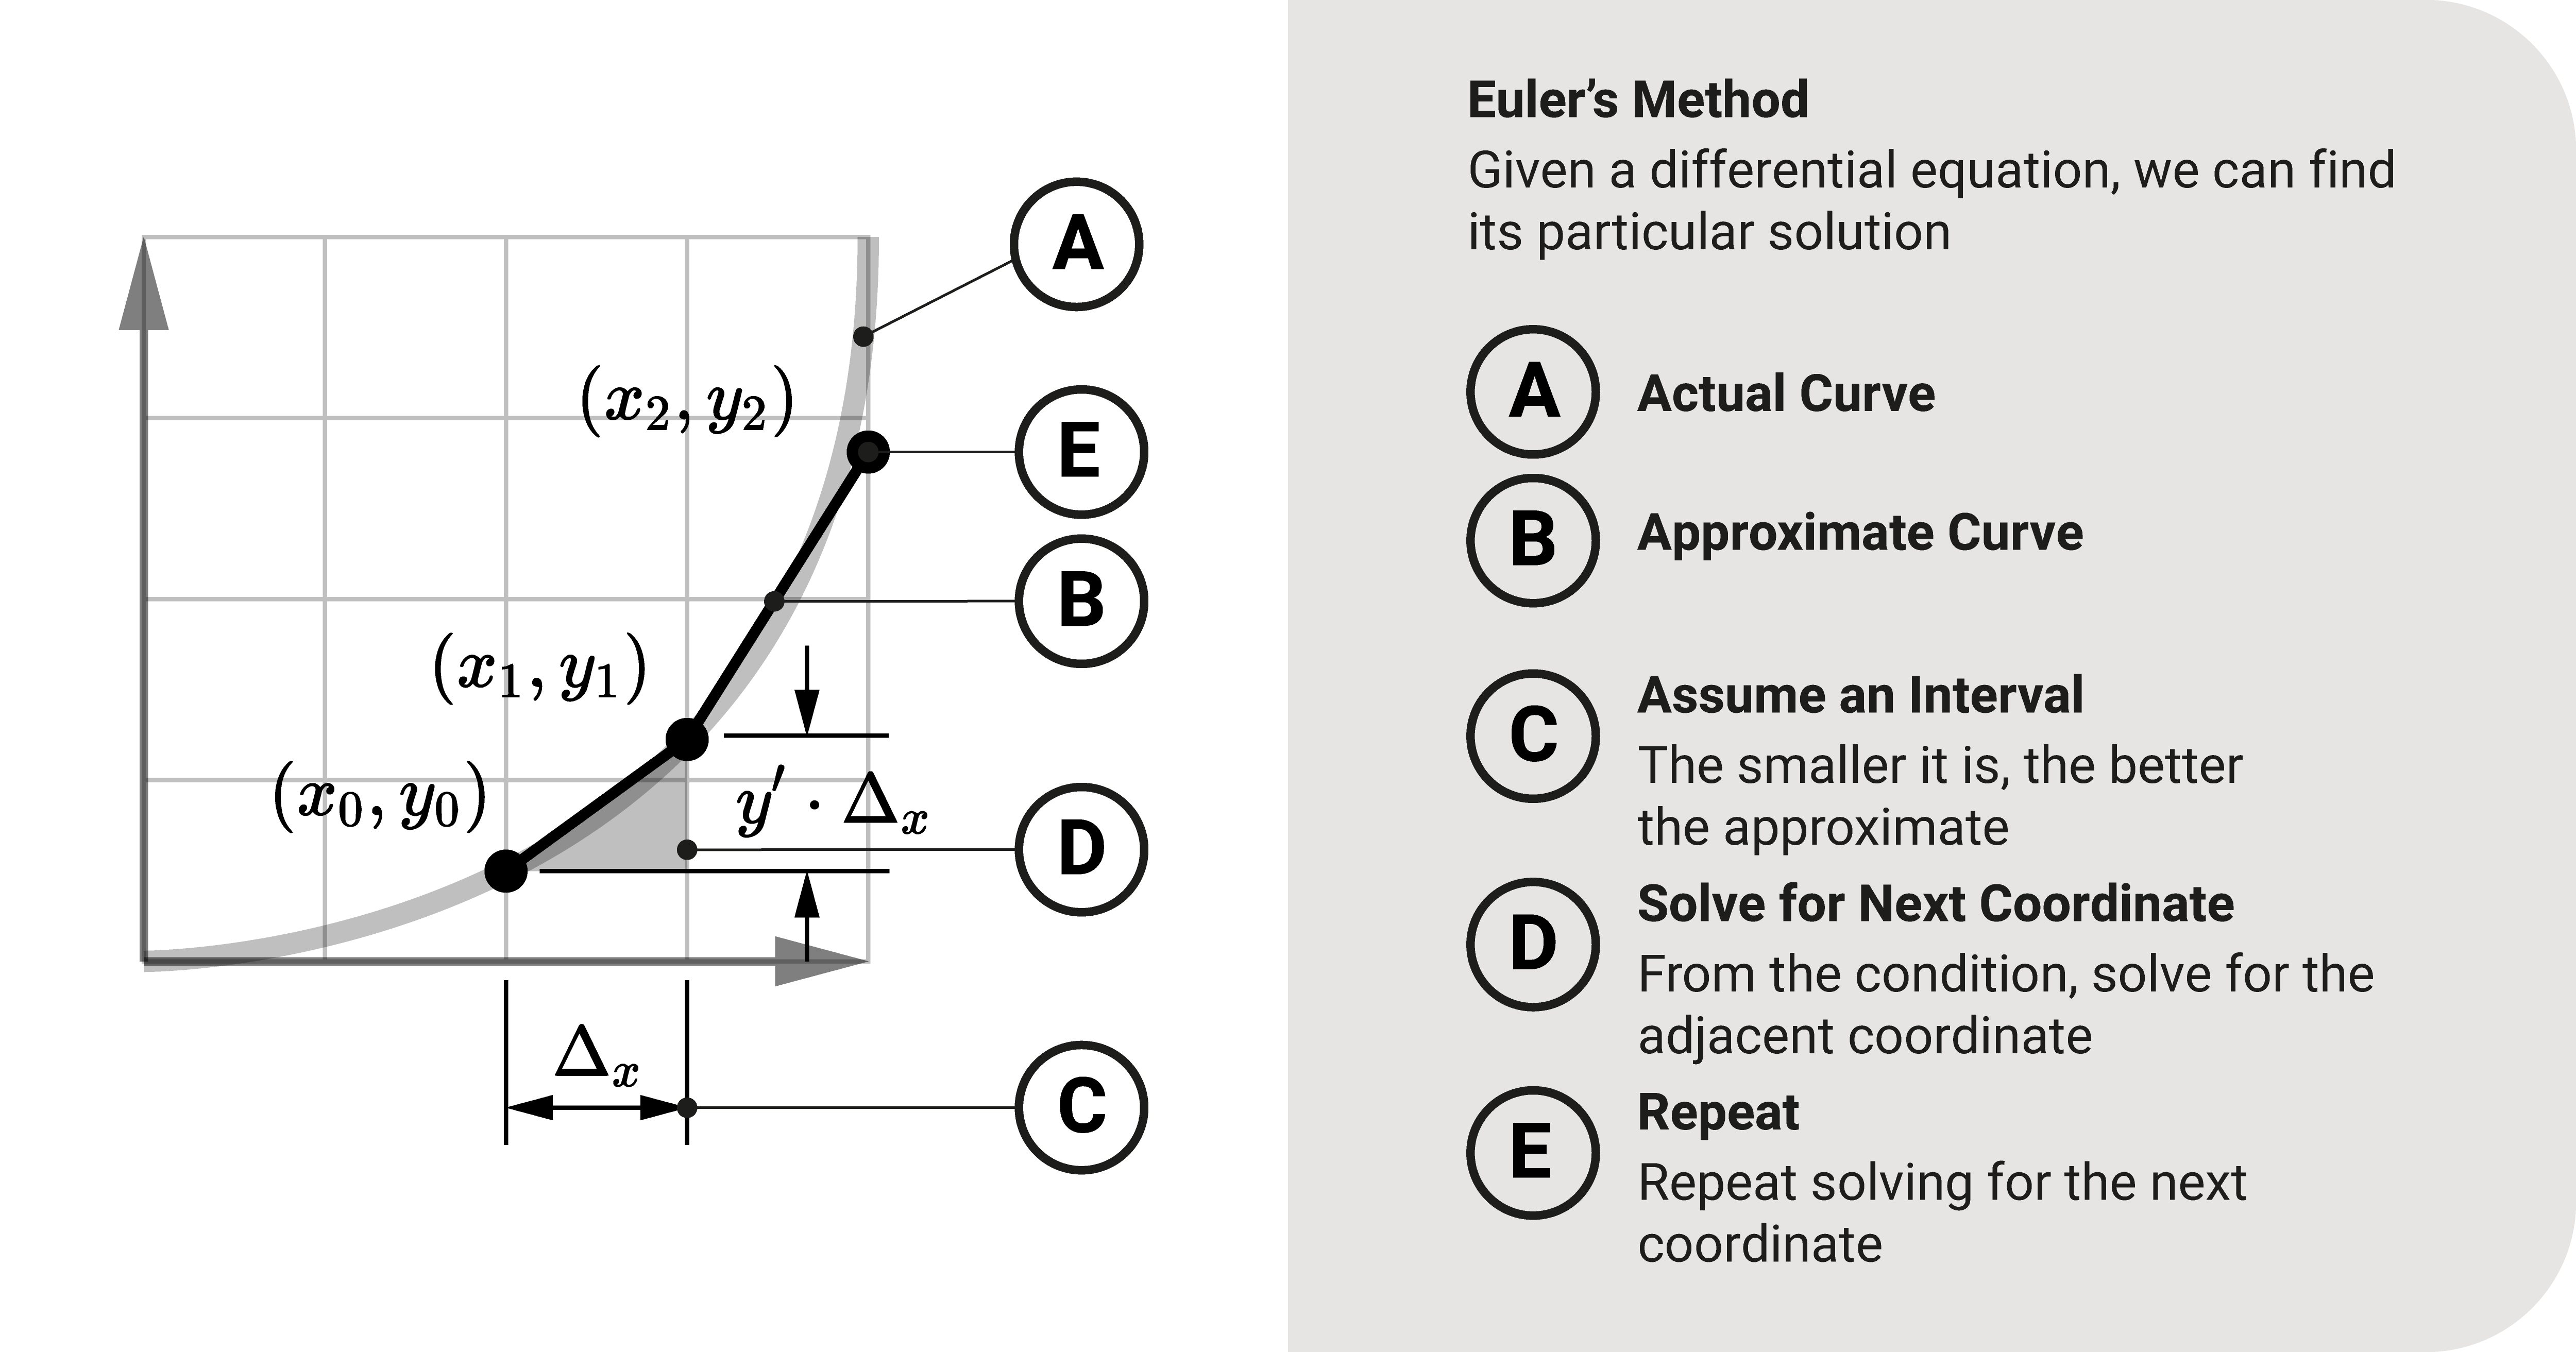

To demonstrate the algorithm it is (hopefully) illustrative to consider an ODE for which we know the analytical (exact) solution.

Consider the initial value problem:


$$\frac{dy(t)}{dt} = 3 - 2 \, t - \frac{1}{2} \, y(t)$$


with initial condition


$$y(0) = 1$$


(Adapted from Boyce and DiPrima)

The solution to this ode is 


$$y(t) = 14 - 4 \, t - 13 \, \text{e}^{-t/2$$


We can plot this analytical (exact) solution by evaluating the solution $y(t)$ at a number of discrete values for time.

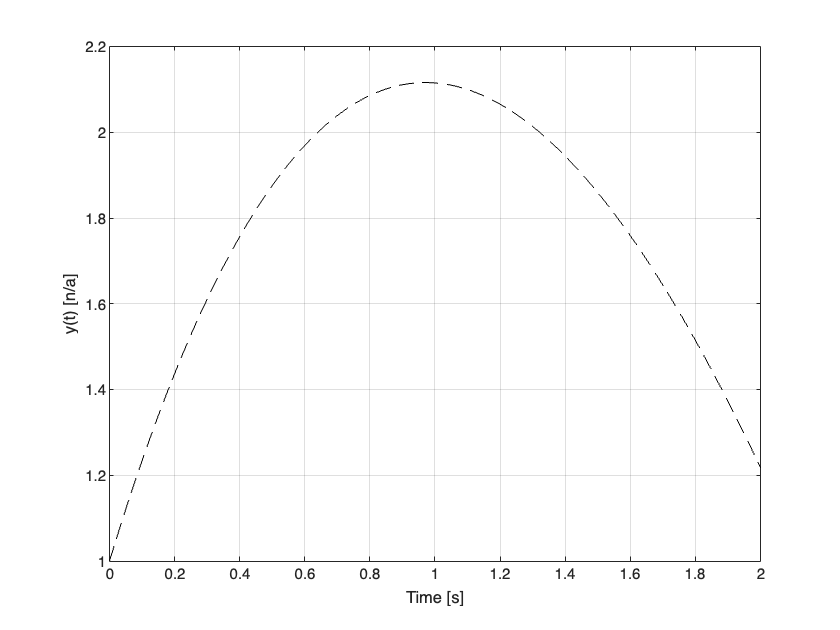

tt = linspace(0, 2, 100);
y_exact = 14-4*tt-13*exp(-tt/2);
figure;
clf;
plot(tt, y_exact, 'k--', 'DisplayName', "Analytical Soln")
hold on
xlabel("Time [s]")
ylabel("y(t) [n/a]")
grid('on')

### Implementing Euler's Method

**Start at Initial Conditions**

Initialize the solution vector with the initial condition.  

t_euler = [0];
y_euler = [1];

**State at current time.**

The current state is our initial condition.

t = t_euler(end);
y = y_euler(end);

**Rate function**

The ODE defines the rate of change of $y(t)$. 


$$\frac{dy(t)}{dt} = 3 - 2 \, t - \frac{1}{2} \, y(t)$$


dydt = 3 -2*t - 0.5*y

dydt = 2.5000

**Time step**

'We can use this tangent line to estimate what the next value of the solution, $y(t)$, but we need to choose a ***fixed discrete time step.   ***A limitation of Euler's method is that we need to know something about the ODE to make an informed choice about the size of the time step.

dt = 0.1;

**Estimate state at next time step.**

t_euler(end+1) = t + dt;
y_euler(end+1) = y + dydt * dt;

Visualize the start, the tangent line and the next discrete step.

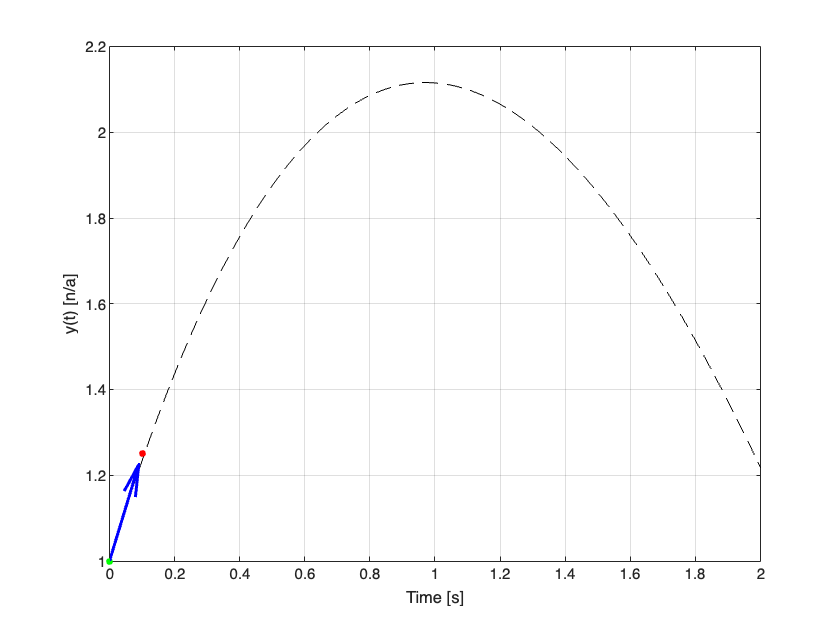

plot(t,y, 'go', 'MarkerSize', 4, 'MarkerFaceColor','g')
quiver(t, y, dt,dydt*dt, 'b', 'MaxHeadSize', 1, 'LineWidth',2)
plot(t_euler(end), y_euler(end), 'ro', 'MarkerSize', 4, 'MarkerFaceColor','r')

**Repeat.**

Then we can do the same thing again

We are currently at time $t[k=2]$ and $y[k=2]$.

t = t_euler(end);
y = y_euler(end);

Find the tagent line from the ODE.

dydt = 3 -2*t - 0.5*y

dydt = 2.1750

and estimate the solution at time $t[k=3]$ and $y[k=3]$.

t_euler(end+1) = t + dt;
y_euler(end+1) = y + dydt * dt;

Visualize

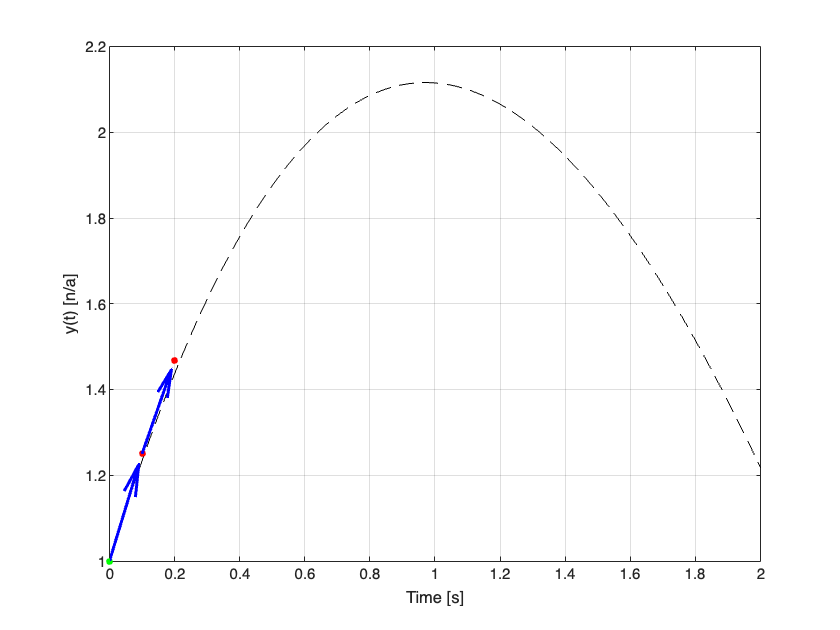

quiver(t, y, dt,dydt*dt, 'b', 'MaxHeadSize', 1, 'LineWidth',2);
plot(t_euler(end), y_euler(end), 'ro', 'MarkerSize', 4, 'MarkerFaceColor','r')

Because we are noticing that we are repeating ourselves and we remember, DRY, it seems like it would be time for a loop.

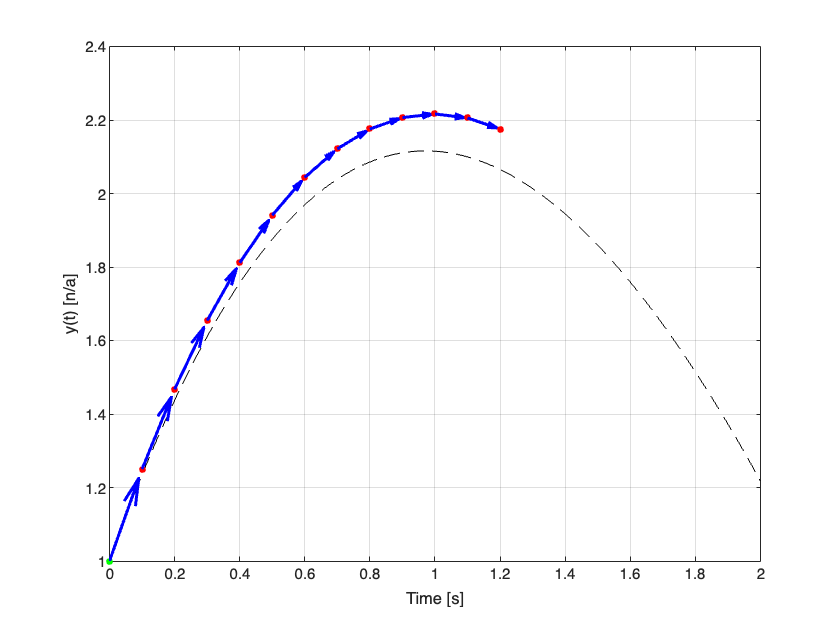

while t_euler(end) < 1.2
    % State at this time step 
    t = t_euler(end);
    y = y_euler(end);
    % Evaluate rate of change 
    dydt = 3 -2*t - 0.5*y;
    % Estimate next time step
    t_euler(end+1) = t + dt;
    y_euler(end+1) = y + dydt * dt;

    % Visualize
    quiver(t, y, dt,dydt*dt, 'b', 'MaxHeadSize', 1, 'LineWidth',2);
    plot(t_euler(end), y_euler(end), 'ro', 'MarkerSize', 4, 'MarkerFaceColor','r')
end

We get a course approximation.  How could we improve the estimate?

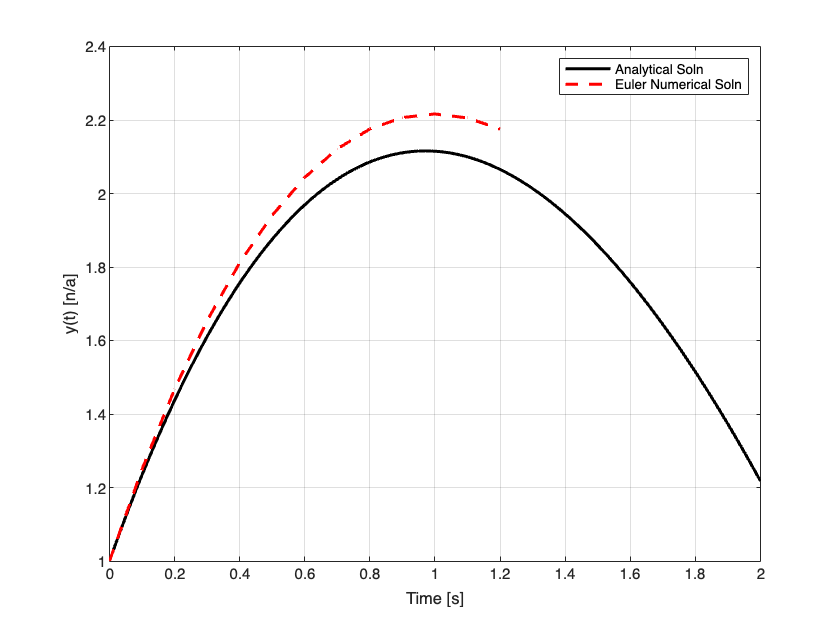

figure;
clf;
plot(tt, y_exact, 'k-', 'linewidth', 2, 'DisplayName', "Analytical Soln")
hold on
plot(t_euler, y_euler, 'r--', 'LineWidth', 2, 'DisplayName', "Euler Numerical Soln")
xlabel("Time [s]")
ylabel("y(t) [n/a]")
grid('on')
legend()

**How good is good enough?**

Understanding and managing errors.

In this simple demonstration we know "truth" from the exact analytical solution, but the whole point of numerical methods is to be able to solve problems that are intractable with analytical techniques.  

A rule of thumb, keep reducing the step size by a factor of two until the solution doesn't change significantly.

In general:

- **Start with a reasonable initial step size,** based on the dynamics of the system. If the dynamics are fast or highly nonlinear, start with a smaller step size. For Euler integration it is typical to set $\Delta t < \frac{T}{100}$, where $T$ is the characteristic time scale of the system.

- **Refine the step size by half.  **If halving the step size changes the solution significantly (often by more than a set tolerance), keep the smaller step size; otherwise, you might not need further reduction.

- **Repeat the halving process** until the change between solutions at successive step sizes is within an acceptable tolerance. This approach, called a **convergence test**, ensures stability and improves accuracy.

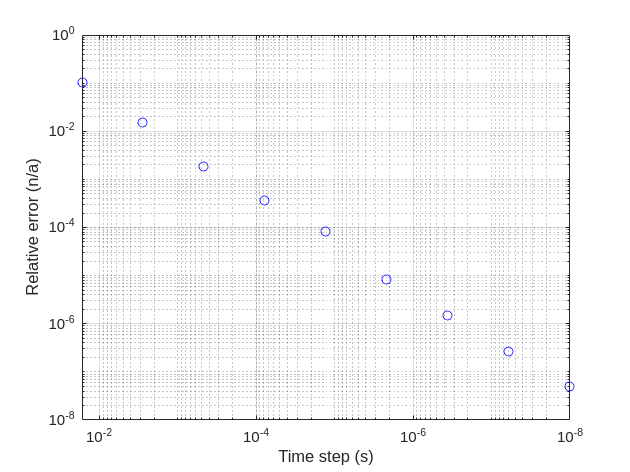

This is to evaluate the change in the final value of y(t) as we decrease step size.  It can be safely ignored.

% DT = logspace(-1,-8,10)
% Y_final = [];
% for ii = 1:length(DT)
%     dt = DT(ii);
%     t_euler = [0];
%     y_euler = [1];
%     while t_euler(end) < 2
%         % State at this time step 
%         t = t_euler(end);
%         y = y_euler(end);
%         % Evaluate rate of change 
%         dydt = 3 -2*t - 0.5*y;
%         % Estimate next time step
%         t_euler(end+1) = t + dt;
%         y_euler(end+1) = y + dydt * dt;
%     end
%     Y_final(ii) = y_euler(end);
% end

% f = figure;
% clf;
% loglog(DT(2:end), abs(diff(Y_final)),'bo')
% xlabel('Time step (s)')
% ylabel('Relative error (n/a)')
% grid('on')
% f.Children(1).XDir = 'reverse';


# Solving ODEs with MATLAB: Part 2, MATLAB Solvers

Overview

- Why?

- Concept of numerical solutions to differential equations

- Method: Euler

- Method: [MATLAB ODE solvers](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html), e.g., [ode45](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

## Recall: General Concept of Numerical Approach 

- Given a ODE - mathematical model of a "system"

- Discretizing the continuous ODE problem

- Applying an iterative numerical scheme

- Understanding and managing errors

Euler's method is a simple implementation of the this generic approach

- Fixed disretization with **user-supplied, fixed step size**.

- Interation is a forward step where the slope (rate of change) from current point is used to estimate next point.

- Small local errors (each time step) accumulate into larger global errors.

- Sensitive to choice of step size.

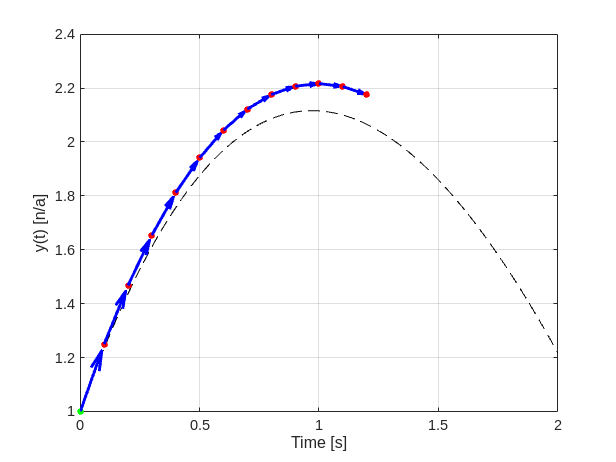

## Separation Principle:  Keep algorithm separate from the problem.

Designing to manage complexity

- **Abstraction:** Design the algorithm to handle general cases rather than specifics, focusing on inputs and outputs that can work across multiple situations.

- **Modularity**: Keep the core logic (like Euler’s method) in a standalone function. This way, the same function can be applied to various ODEs without modifying its internals.

For example, 

**Problem:**  First order LTI, ODE 


$$\dot{y}(t,y) = 3 - 2 \, t - \frac{1}{2} \, y  \\
y(0) = 1
$$


**Solver:** Euler numerical integration


$$y_{n+1} = y_n + \dot{y}(t_n, y_n) \, \Delta t   \, \, \, \, \, \, \, n=1,2,3, \ldots$$


As we saw with the `fzero` examples, a good way to separate an algorithm from the specific application is to use a *function handle *to pass the problem to the solver.  Sor for Euler's method this might look like...

**Define the problem as a function**

function dydt = boyce(t, y)
    dydt = 3 - 2*t - 0.5*y;
end

Then we can define a general purpose **Euler solver.**  We only need to change the function handle to apply to other specific cases.

% Specify the problem as a function handle and point it to our example
rate_func = @boyce;

% Initial conditions
t_euler = [0];
y_euler = [1];
% Time span - as a 2x1 vector

dt = 0.1000

tspan = [0, 2.0];
% Time step: define as number of steps 
N = 20;
dt = (tspan(2) - tspan(1))/N
% Iteration to implement Euler
while t_euler(end) < tspan(2)
    dydt = rate_func(t_euler(end), y_euler(end));
    t_euler(end+1) = t_euler(end) + dt;
    y_euler(end+1) = y_euler(end) + dydt * dt;
end

Visualize with the exact solution for reference.

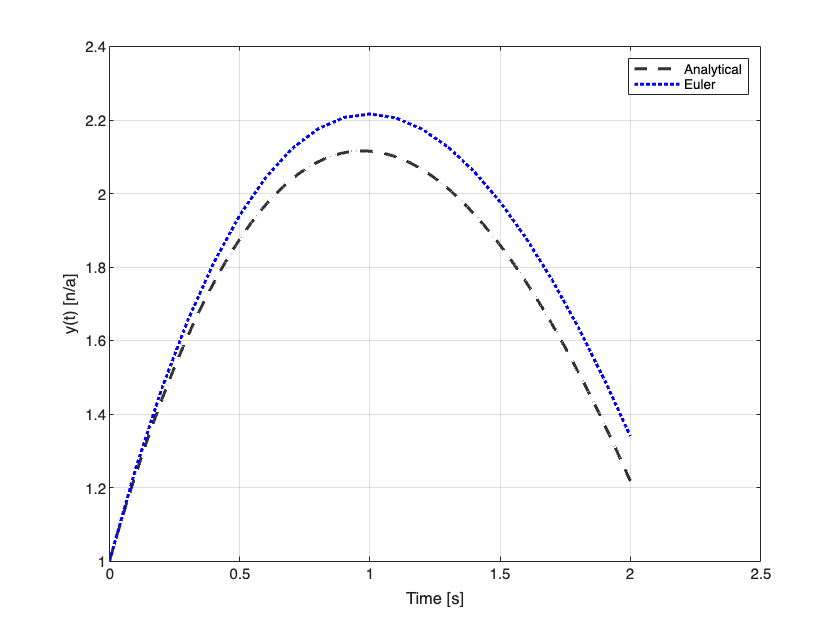

% Visualize
figure(1);
clf;
tt = linspace(0, 2, 100);
y_exact = 14-4*tt-13*exp(-tt/2);
figure;
clf;
plot(tt, y_exact, '--', 'Color', [0.2 0.2 0.2], 'linewidth',2, 'DisplayName', "Analytical")
hold on
plot(t_euler, y_euler,'b:','linewidth', 2, 'DisplayName','Euler')
xlabel("Time [s]")

ylabel("y(t) [n/a]")
grid('on')
legend()

## MATLAB ODE Solvers

MATLAB offers a varitey of solver options ([MATLAB ODE solvers](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)).  While the have different features, they all share an **interface**.  

*"An ****interface**** is a contract to perform a certain task in exchange for a set of parameters"* - Bjarne Stroustrup (C++ creator)

The generuc ODE Solver Interface

`[t,y] = odeXX(odefun,tspan,y0,options)`

Inputs:

- odefun - Function handle specifying the problem we want to solve.  The signature for the funciton must be `dydt = odefun(t,y)`

- tspan - Interval of time (beginning to end) for the solution

- y0 - Initial condition

- options - (optional) Option structure to control the details of the solver's behavior.

Outputs:

- t - Evaluation points as a vector.

- y - Solution values as an array

(There are more optional outputs which we may cover later.)

### Example: ode45

The [ode45](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html) solver is a popular choice for "typical" problems because it balances accuracy (error) with cost (computational time) and gives reliable results for most non-stiff problems.

**Problem:**


$$\dot{y}(t,y) = 3 - 2 \, t - \frac{1}{2} \, y  \\
y(0) = 1
$$


Define our inputs to the solver interface.

odefun = @boyce;
tspan = [0, 2.0];
y0 = 1.0;

Then solve and visualize

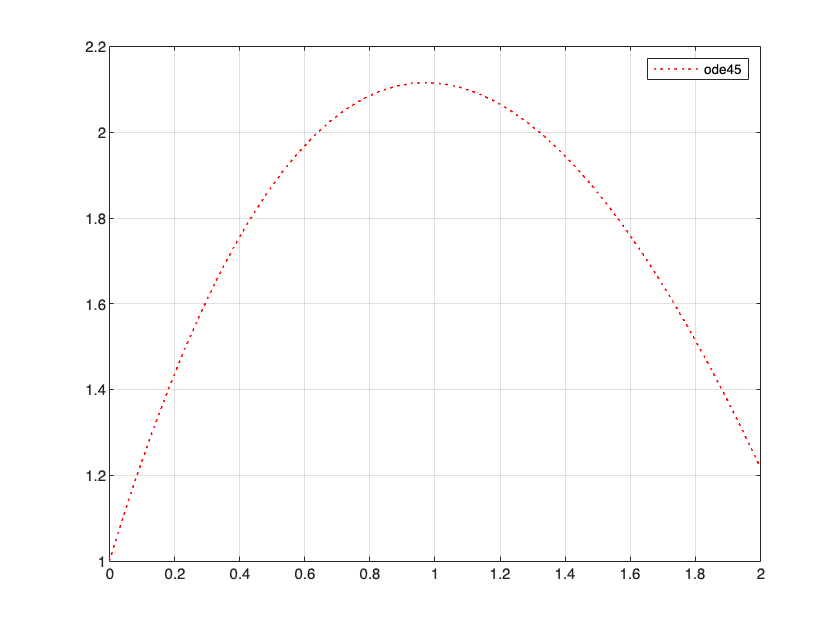

[t_ode, y_ode] = ode45(odefun, tspan, y0);
figure(1)
plot(t_ode,y_ode, 'r:', 'linewidth',1  , 'DisplayName','ode45')
grid('on')
legend()

**Visuzalize the ode45 method.**

This is adapted from the PMM section.  The details of the implementation can be skipped - the intent is to provide some introspection on how ode45 operates.  It does use one of the ode solver options which are listed here: [Summary of ODE Options](https://www.mathworks.com/help/matlab/math/summary-of-ode-options.html).

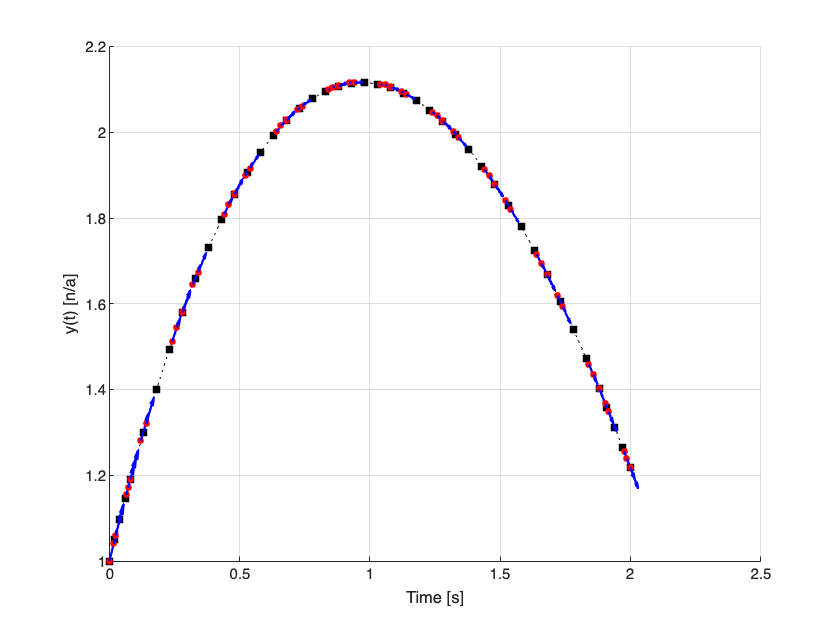

11 successful steps
0 failed attempts
67 function evaluations


function dydt = boyce_viz(t, y)
    dydt = 3 - 2*t - 0.5*y;
    plot(t, y, 'ro','MarkerSize', 4, 'MarkerFaceColor','r');
    quiver(t, y, 1, dydt, 0.03, 'b', 'MaxHeadSize', 1, 'LineWidth',1.5)
end

figure(2);
clf;
hold on
plot(tt, y_exact,'k:')

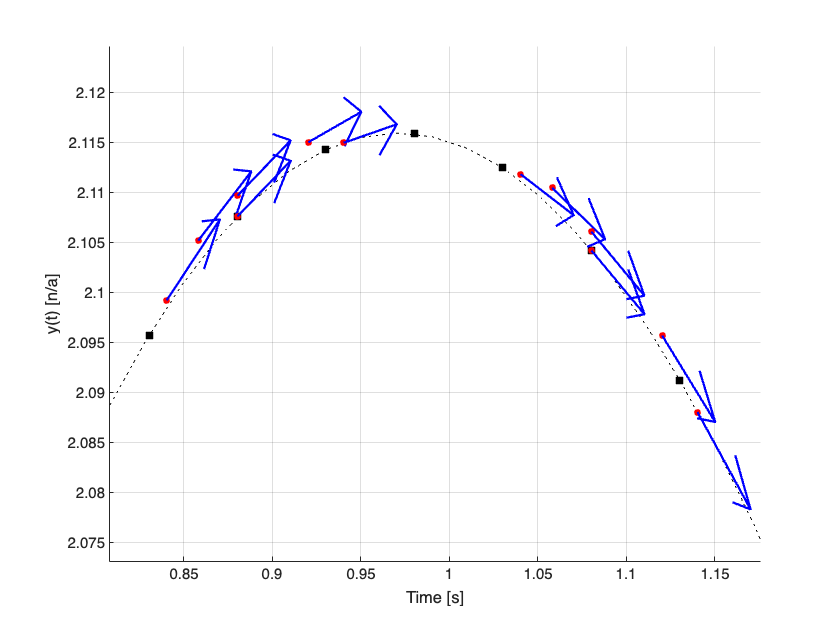

plot(t_ode, y_ode, 'ks', 'MarkerFaceColor','k')
xlabel("Time [s]")
ylabel("y(t) [n/a]")
grid('on')
options = odeset('Refine', 1, 'Stats', 'on');

[t_ode, y_ode] = ode45(@boyce_viz, tspan, y0, options);

- Black squares show the timesteps were ode45 evaluated the ODE.  Note that the timesteps are shorter when the solution is changing more quickly.

- Red circles show where ode45 evaluated the ODE to rate function to improve the estimate

**Zoom**

xlim([0.808 1.176])
ylim([2.0731 2.1246])